# Main function: define the map, find the path

function astar_collision_avoidance()
    % Define the grid, 1 means obstacle, 0 means free path, 2 means collision region
grid =  [
    [0, 0, 0, 0, 0, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 0, 0, 0, 0, 0],
    [0, 0, 0, 0, 0, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 0, 0, 0, 0, 0],
    [0, 0, 0, 0, 0, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 0, 0, 0, 0, 0],
    [0, 0, 0, 0, 0, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 0, 0, 0, 0, 0],
    [0, 0, 0, 0, 0, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 0, 0, 0, 0, 0],
    [0, 0, 0, 0, 0, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 0, 0, 0, 0, 0],
    [0, 0, 0, 0, 0, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 0, 0, 0, 0, 0],
    [0, 0, 0, 0, 0, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 0, 0, 0, 0, 0],
    [0, 0, 0, 0, 0, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 0, 0, 0, 0, 0],
    [0, 0, 0, 0, 0, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 0, 0, 0, 0, 0],
    [0, 0, 0, 0, 0, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 0, 0, 0, 0, 0],
    [0, 0, 0, 0, 0, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 0, 0, 0, 0, 0],
    [0, 0, 0, 0, 0, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 0, 0, 0, 0, 0],
    [0, 0, 0, 0, 0, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 0, 0, 0, 0, 0],
    [0, 0, 0, 0, 0, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 0, 0, 0, 0, 0],
    [0, 0, 0, 0, 0, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 0, 0, 0, 0, 0],

    [0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 2, 2, 2, 2, 2, 2, 2, 2, 2, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0],

    [0, 0, 0, 0, 0, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 0, 0, 0, 0, 0],
    [0, 0, 0, 0, 0, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 0, 0, 0, 0, 0],
    [0, 0, 0, 0, 0, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 0, 0, 0, 0, 0],
    [0, 0, 0, 0, 0, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 0, 0, 0, 0, 0],
    [0, 0, 0, 0, 0, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 0, 0, 0, 0, 0],
    [0, 0, 0, 0, 0, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 0, 0, 0, 0, 0],
    [0, 0, 0, 0, 0, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 0, 0, 0, 0, 0],
    [0, 0, 0, 0, 0, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 0, 0, 0, 0, 0],
    [0, 0, 0, 0, 0, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 0, 0, 0, 0, 0],
    [0, 0, 0, 0, 0, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 0, 0, 0, 0, 0],
    [0, 0, 0, 0, 0, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 0, 0, 0, 0, 0],
    [0, 0, 0, 0, 0, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 0, 0, 0, 0, 0],
    [0, 0, 0, 0, 0, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 0, 0, 0, 0, 0],
    [0, 0, 0, 0, 0, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 0, 0, 0, 0, 0],
    [0, 0, 0, 0, 0, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 0, 0, 0, 0, 0],
    [0, 0, 0, 0, 0, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 0, 0, 0, 0, 0],
    [0, 0, 0, 0, 0, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 0, 0, 0, 0, 0],
    [0, 0, 0, 0, 0, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 1, 1, 1, 1, 1, 1, 1, 0, 0, 0, 0, 0, 0],

    [0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0],
    [0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0],
];

    % Define the starting and goal points for the two robots
    start1 = [15, 3];
    goal1 = [8, 22];
    start2 = [17, 17];
    goal2 = [6, 14];

    item1 = [8, 21];
    item2 = [6, 13];


    % Initialize the figure for animation
    figure;
    imagesc(grid);
    colormap(gray);
    hold on;
    robot1_plot = plot(start1(2), start1(1), 'ro', 'MarkerFaceColor', 'r');
    robot2_plot = plot(start2(2), start2(1), 'bo', 'MarkerFaceColor', 'b');

    item1_plot = plot(item1(2), item1(1), 'r*', 'MarkerFaceColor', 'r');
    item2_plot = plot(item2(2), item2(1), 'b*', 'MarkerFaceColor', 'b');


    % Plot the collision region
    [collision_rows, collision_cols] = find(grid == 2);
    for k = 1:length(collision_rows)
        rectangle('Position', [collision_cols(k)-0.5, collision_rows(k)-0.5, 1, 1], ...
                  'EdgeColor', 'g', 'LineWidth', 2);
    end

    % Find paths for both robots using A* algorithm
    path1_to_goal = astar(grid, start1, goal1);
    path2_to_goal = astar(grid, start2, goal2);

    % Robots' paths from goal back to start
    path1_to_start = astar(grid, goal1, start1);
    path2_to_start = astar(grid, goal2, start2);

    % Combine paths to form round trips
    path1 = [path1_to_goal; path1_to_start];
    path2 = [path2_to_goal; path2_to_start];

    % Handle collision region
    [final_path1, final_path2] = handle_collision(path1, path2, grid, robot1_plot, robot2_plot);

    % Display the final paths
    disp('Robot 1 Path:');
    disp(final_path1);
    disp('Robot 2 Path:');
    disp(final_path2);
end


# A* function

function path = astar(grid, start, goal)
    % Implement the A* algorithm to find the shortest path from start to goal

    % Initialize the open and closed lists
    open_list = start;
    closed_list = [];
    
    % Initialize the g, h, and f scores
    g_score = Inf(size(grid));
    g_score(start(1), start(2)) = 0;
    h_score = heuristic(start, goal);
    f_score = Inf(size(grid));
    f_score(start(1), start(2)) = h_score;

    % Initialize the came_from map
    came_from = cell(size(grid));
    
    path = [];
    while ~isempty(open_list)
        % Find the node with the lowest f_score
        [~, idx] = min(f_score(sub2ind(size(f_score), open_list(:, 1), open_list(:, 2))));
        current = open_list(idx, :);
        
        % If the goal is reached, reconstruct the path
        if isequal(current, goal)
            path = reconstruct_path(came_from, current);
            return;
        end
        
        % Move current node from open to closed list
        open_list(idx, :) = [];
        closed_list = [closed_list; current];
        
        % Get the neighbors of the current node
        neighbors = get_neighbors(current, size(grid));
        
        for i = 1:size(neighbors, 1)
            neighbor = neighbors(i, :);
            
            % Ignore the neighbor if it's in the closed list or an obstacle
            if ismember(neighbor, closed_list, 'rows') || grid(neighbor(1), neighbor(2)) == 1
                continue;
            end
            
            % Tentative g score
            tentative_g_score = g_score(current(1), current(2)) + 1;
            
            % If the neighbor is not in the open list, add it
            if ~ismember(neighbor, open_list, 'rows')
                open_list = [open_list; neighbor];
            elseif tentative_g_score >= g_score(neighbor(1), neighbor(2))
                continue;
            end
            
            % Update the scores and came_from map
            came_from{neighbor(1), neighbor(2)} = current;
            g_score(neighbor(1), neighbor(2)) = tentative_g_score;
            h_score = heuristic(neighbor, goal);
            f_score(neighbor(1), neighbor(2)) = g_score(neighbor(1), neighbor(2)) + h_score;
        end
    end
    
    error('No path found');
end

function h = heuristic(node, goal)
    % Heuristic function for A* (Manhattan distance)
    h = abs(node(1) - goal(1)) + abs(node(2) - goal(2));
end

function neighbors = get_neighbors(node, grid_size)
    % Get the neighbors of a node (4-connectivity)
    neighbors = [];
    for d = [-1 0; 1 0; 0 -1; 0 1]'
        neighbor = node + d';
        if all(neighbor > 0 & neighbor <= grid_size)
            neighbors = [neighbors; neighbor];
        end
    end
end

function path = reconstruct_path(came_from, current)
    % Reconstruct the path from the came_from map
    path = current;
    while ~isempty(came_from{current(1), current(2)})
        current = came_from{current(1), current(2)};
        path = [current; path];
    end
end

# Collision handle function, and animation generation function

function [final_path1, final_path2] = handle_collision(path1, path2, grid, robot1_plot, robot2_plot)
    % Handle collision in the defined region by making one robot wait
    final_path1 = [];
    final_path2 = [];
    i = 1;
    j = 1;
    
    while i <= size(path1, 1) || j <= size(path2, 1) 
        % Determine if robots are in the collision region
        if i <= size(path1, 1)
            robot1_in_collision_region = is_in_collision_region(path1(i, :), grid);
        else
            robot1_in_collision_region = false;
        end

        if j <= size(path2, 1)
            robot2_in_collision_region = is_in_collision_region(path2(j, :), grid);
        else
            robot2_in_collision_region = false;
        end

        
        % Move both robots simultaneously if no collision
        if ~robot1_in_collision_region && ~robot2_in_collision_region
            if i <= size(path1, 1)
                set(robot1_plot, 'XData', path1(i, 2), 'YData', path1(i, 1));
                final_path1 = [final_path1; path1(i, :)];
                i = i + 1;
            end
            if j <= size(path2, 1)
                set(robot2_plot, 'XData', path2(j, 2), 'YData', path2(j, 1));
                final_path2 = [final_path2; path2(j, :)];
                j = j + 1;
            end

        % Robot 1 is in collision region, Robot 2 keeps moving if its next step is not in the collision region
        elseif robot1_in_collision_region && ~robot2_in_collision_region       
            if i <= size(path1, 1)
                set(robot1_plot, 'XData', path1(i, 2), 'YData', path1(i, 1));
                final_path1 = [final_path1; path1(i, :)];
                i = i + 1;
            end
            % Robot 2 adds the same position to wait
            if j < size(path2, 1) && ~is_in_collision_region(path2(j + 1, :), grid)
                set(robot2_plot, 'XData', path2(j, 2), 'YData', path2(j, 1));
                final_path2 = [final_path2; path2(j, :)];
                j = j + 1;
            elseif j <= size(path2, 1)
                set(robot2_plot, 'XData', path2(j, 2), 'YData', path2(j, 1));
                if isempty(final_path2)
                    final_path2 = [final_path2; path2(j, :)];
                else
                    final_path2 = [final_path2; final_path2(end, :)];
                end
            end

        % Robot 2 is in collision region, Robot 1 keeps moving if its next step is not in the collision region
        elseif robot2_in_collision_region && ~robot1_in_collision_region
            if j <= size(path2, 1)
                set(robot2_plot, 'XData', path2(j, 2), 'YData', path2(j, 1));
                final_path2 = [final_path2; path2(j, :)];
                j = j + 1;
            end
            % Robot 1 adds the same position to wait
            if i < size(path1, 1) && ~is_in_collision_region(path1(i + 1, :), grid)
                set(robot1_plot, 'XData', path1(i, 2), 'YData', path1(i, 1));
                final_path1 = [final_path1; path1(i, :)];
                i = i + 1;

            elseif i <= size(path1, 1)
                set(robot1_plot, 'XData', path1(i, 2), 'YData', path1(i, 1));
                if isempty(final_path1)
                    final_path1 = [final_path1; path1(i, :)];
                else
                    final_path1 = [final_path1; final_path1(end, :)];
                end
            end

        % Both robots are about to enter the collision region at the same time
        elseif robot1_in_collision_region && robot2_in_collision_region
            if j < size(path2, 1) && ~is_in_collision_region(path2(j + 1, :), grid)
                set(robot2_plot, 'XData', path2(j, 2), 'YData', path2(j, 1));
                final_path2 = [final_path2; path2(j, :)];
                j = j + 1;
            elseif i < size(path1, 1) && ~is_in_collision_region(path1(i + 1, :), grid)
                set(robot1_plot, 'XData', path1(i, 2), 'YData', path1(i, 1));
                final_path1 = [final_path1; path1(i, :)];
                i = i + 1;
            end
        end
        
        % Update the plot
        drawnow;
        pause(0.5); % Adjust the pause duration as needed
    end
end


function in_region = is_in_collision_region(position, grid)
    % Check if the given position is within the collision region
    in_region = grid(position(1), position(2)) == 2;
end

# Call the main function

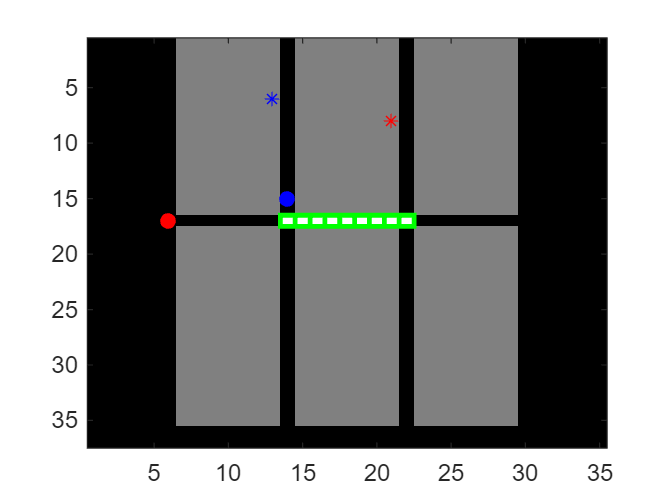

astar_collision_avoidance()